# RESULT: Arm Design Comparison

*MATLAB Version: '23.2.0.2409890 (R2023b) Update 3'*

*Last revised: 8/4/2024*

*Authors: Bill Fan*

This document should contain all that is necessary for the RESULTS subsection on applying the attainability methods for demonstrating the benefits of antagonistic arm design.

#### Test 1 

**Purpose: **Use the attainable reaction space to demonstrate that antagonistic arms are more capable than non-antagonistic ones. 

**Methadology**:

Create arm_design structs to define the following three arms:

- 4 muscle non-antagonistic arm

- 4 bellow non-antagonistic arm

- 2 muscle 2 bellow antagonistic arm

%%% Define baseline parameters:
rho_outer = 0.08;
rho_inner = 0.015;

% Actuator position radii and the associated moment-arm matrix
rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
    1, 1, 1, 1;
    0, 0, 0, 0;
    -rhos;
    ];

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Assemble it all into structs
struct_design_base = struct();
struct_design_base.mat_A = mat_A;
struct_design_base.rhos = rhos;
struct_design_base.l_0 = l_0;
struct_design_base.g_0 = g_0;

% Muscle force functions
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;

%%% Create variations 
struct_antagonist = struct_design_base;
struct_antagonist.fs = {f_bellow, f_muscle, f_muscle, f_bellow};
struct_antagonist.p_bounds = [50; 100; 100; 50];

struct_4muscle= struct_design_base;
struct_4muscle.fs = {f_muscle, f_muscle, f_muscle, f_muscle};
struct_4muscle.p_bounds = [100; 100; 100; 100];

struct_4bellow= struct_design_base;
struct_4bellow.fs = {f_bellow, f_bellow, f_bellow, f_bellow};
struct_4bellow.p_bounds = [50; 50; 50; 50];

arm_designs = {struct_4bellow, struct_antagonist};
N_arms = numel(arm_designs);

We will compare these arms across six representative arm base-curve shapes - subject to change

% Generate test cases
l = 0.5;

f_affine_curvature = @(s, a, b) [
    l*ones(size(s)); % TODO: This seems suspect - but for these tests it's really hard to consider what this should be
    zeros(size(s));
    a*s + b
    ];

f_cubic_curvature = @(s, a, b, c, d) [
    l*ones(size(s));
    zeros(size(s));
    a*s.^3 + b*s.^2 + c*s + d;
    ];

s = linspace(0, 1, N_poses);

% % TODO: maybe rewrite this to just be a stack of matrices?
% cell_segment_twists = cell(2, 3);
% 
% cell_segment_twists{1, 1} = f_affine_curvature(s, -1, 1);
% cell_segment_twists{2, 1} = f_affine_curvature(s, 1, 2);
% 
% cell_segment_twists{1, 2} = f_cubic_curvature(s, 5, 0, 0, 0);
% cell_segment_twists{2, 2} = f_cubic_curvature(s, -10, 10, 0, 0);
% 
% % Discontinuous cases
% cell_segment_twists{1, 3} = [
%     l*ones(size(s));
%     zeros(size(s));
%     (1 - round(s)).*-2 + (round(s) .* 3)
%     ];
% 
% cell_segment_twists{2, 3} = [
%     l*ones(size(s));
%     zeros(size(s));
%     (1 - round(s)).*(-5*s+1) + (round(s) .* (-s+2))
%     ];


#### Figure 2 code - "representative shapes" version

%%% Define arm shapes
% Choose four test shapes and put them in a cell-array
cell_segment_twists = cell(1, 3);

cell_segment_twists{1} = f_affine_curvature(s, -3, 3);
cell_segment_twists{2} = f_affine_curvature(s, 1, 1.5);
cell_segment_twists{3} = f_affine_curvature(s, 6, -1.5);
N_shapes = numel(cell_segment_twists);
%cell_segment_twists{4} = f_affine_curvature(s, 2, -0.5);


%%% Sample random tip loads
% For each arm, test N number of different test reactions and see how many
% are predicted to be attainable by our method

% First we generate the tip loads
F_x_scale = 20;
F_y_scale = 20;
tau_scale = 5;
K_scales = diag([F_x_scale, F_y_scale, tau_scale]);

rng(100);
N_test_Qs = 100;
Q_tests = K_scales* (rand(3, N_test_Qs) - 0.5);
mat_s_Q_samples = repmat(s, [N_test_Qs, 1]);

% For each tip load, compute the corresponding loads that they induce 
% at each point along the lengths of each above arm

cell_q_tests = cell(size(cell_segment_twists));
all_q_test_traces_f = zeros(N_poses, N_test_Qs, numel(cell_segment_twists));
all_q_test_traces_m = zeros(N_poses, N_test_Qs, numel(cell_segment_twists));
for i_arm = 1 : numel(cell_segment_twists)
    cell_q_tests{i_arm} = zeros(3, N_poses, N_test_Qs);
    segment_twists_i = cell_segment_twists{i_arm};
    
    for i_test = 1 : N_test_Qs
        Q_test_i = Q_tests(:, i_test);
        cell_q_tests{i_arm}(:, :, i_test) = calc_external_wrench(segment_twists_i, Q_test_i, g_0);
    end
    
    [all_q_test_traces_f(:, :, i_arm), all_q_test_traces_m(:, :, i_arm)] = mat_wrenches_to_traces(cell_q_tests{i_arm});
end

relative_qf_test_all = all_q_test_traces_f(:, :, :) - all_q_test_traces_f(1, :, :);
relative_qm_test_all = all_q_test_traces_m(:, :, :) - all_q_test_traces_m(1, :, :);

%%% Compute the attainable reaction space
% First we need to compute the reactions. TODO: this should be a function?
N_ps_per_edge = 2;
ps_edges = sample_edges_of_cuboid(N_ps_per_edge, arm_designs{1}.p_bounds);
N_ps = size(ps_edges, 2);

% For each arm base-curve shape:
cell_bndry_af = cell(size(cell_segment_twists));
cell_bndry_am = cell(size(cell_segment_twists));
for i_shape = 1 : numel(cell_segment_twists)
    twists_i = cell_segment_twists{i_shape};

    all_bndry_af = zeros(N_poses, N_ps, numel(arm_designs));
    all_bndry_am = zeros(N_poses, N_ps, numel(arm_designs));
    
    % For each arm design: compute the reaction prism
    for i_design = 1 : numel(arm_designs)
        struct_design_i = arm_designs{i_design};

        % Sample pressures from this arm design's pressure bounds
        % TODO: Can do this once for each design before the loop
        ps_edges = sample_edges_of_cuboid(N_ps_per_edge, struct_design_i.p_bounds);

        % Compute the reaction traces for the boundary pressures, for this
        % arm held at this shape. 
        [bndry_traces_f, bndry_traces_m] = compute_reaction_traces(ps_edges, twists_i, struct_design_i);
        
        % Store everything
        all_bndry_af(:, :, i_design) = bndry_traces_f;
        all_bndry_am(:, :, i_design) = bndry_traces_m;
    end

    cell_bndry_af{i_shape} = all_bndry_af;
    cell_bndry_am{i_shape} = all_bndry_am;
end

%%% For each load for each shape, find the closest matching attainable arm
%%% shape.
%error("Warning: this will take (8 * number of Qs) seconds to run.")
cell_residuals = cell(N_shapes, N_arms);
cell_p_solns = cell(N_shapes, N_arms);
tic
for i_shape = 1 : numel(cell_segment_twists)
    segment_twists_i = cell_segment_twists{i_shape};
    for i_design = 1 : numel(arm_designs)
        arm_design_i = arm_designs{i_design};
        
        [cell_residuals{i_shape, i_design}, cell_p_solns{i_shape, i_design}] = test_attainability_across_loads(Q_tests, segment_twists_i, arm_design_i);

    end

Elapsed time is 741.507613 seconds.


end
toc

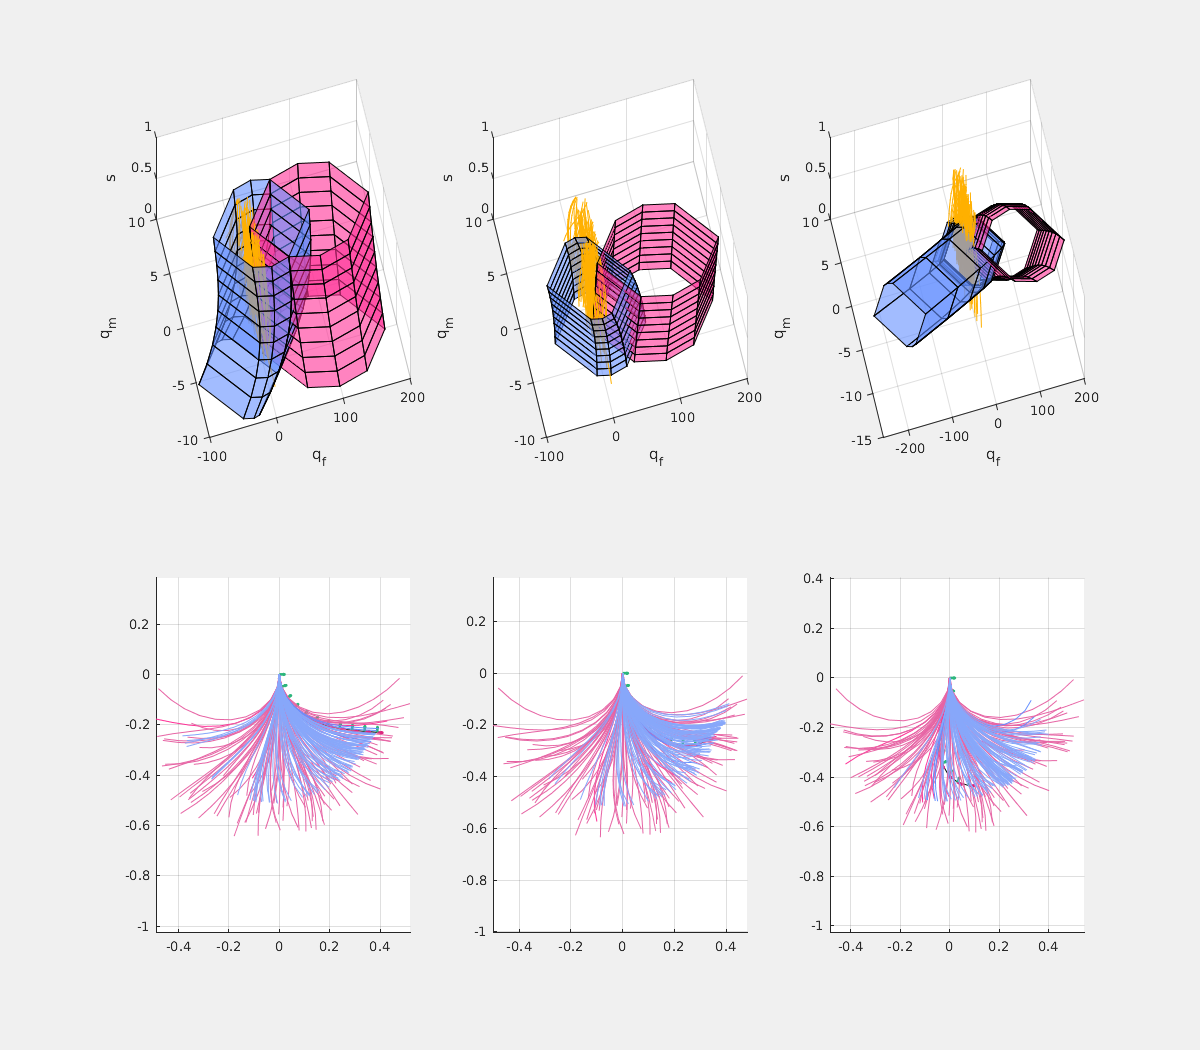

Shape 3 arm 2 residual too high - res = 22.331 
Shape 3 arm 2 residual too high - res = 27.761 
Shape 3 arm 2 residual too high - res = 18.840 


figure("Visible", true, "Position", [0, 0, 1200, 1050], "Renderer", "Painters");

i_cutoff = round(N_test_Qs/20);

for i_shape= 1 : numel(cell_segment_twists)
    ax = subplot(2, 3, i_shape);
    hold on

    % Get all of the boundary traces for this shape
    bndry_traces_f_i = cell_bndry_af{i_shape};
    bndry_traces_m_i = cell_bndry_am{i_shape};
    
    % For each arm design held at this shape:
    for i_design = 1 : numel(arm_designs)
        % Get the correctly-ordered indices of points along the boundary of
        % the base. This way the plot correctly shows the perimeter,
        % without criss-crossing the interior.[] / 255
        i_bndry = boundary(squeeze(bndry_traces_f_i(1, :, i_design))', squeeze(bndry_traces_m_i(1, :, i_design))', 0);

        plot_style = struct("facealpha", 0.6, "linewidth", 0.5);
        plot_wrench_hull(bndry_traces_f_i(:, i_bndry, i_design), bndry_traces_m_i(:, i_bndry, i_design), ax, colors(i_design, :), plot_style);
    end

    plot3(all_q_test_traces_f(:, : ,i_shape), all_q_test_traces_m(:, : ,i_shape), mat_s_Q_samples', "color", color_yellow)
    
    xlabel("q_f")
    ylabel("q_m")
    zlabel("s")
    grid on
    view(-15, 70)
end

for i = 1 : numel(cell_segment_twists)
    ax = subplot(2, 3, i+3);
    hold on
    segment_twists_ij = cell_segment_twists{i};
    poses = calc_poses(g_0, segment_twists_ij);
    plot_poses(poses, ax);

    for i_design = 1:N_arms
        residuals_i = cell_residuals{i, i_design};

        [~, i_sort] = sort(residuals_i);
        Q_sorted_i = Q_tests(:, i_sort);
        p_sorted_i = cell_p_solns{i, i_design}(:, i_sort);

        for i_load = 1 : i_cutoff
            segment_twists_i = solve_equilibrium_shape(N_poses, arm_designs{i_design}, p_sorted_i(:, i_load), Q_sorted_i(:, i_load));
            poses_i = calc_poses(g_0, segment_twists_i);
            plot_poses(poses_i, ax, struct("color", colors(i_design, :)), false);

            res = check_equilibrium_norm_modified(segment_twists_i, Q_sorted_i(:, i_load), p_sorted_i(:, i_load), arm_designs{i_design});
            if res > 1e-5
                fprintf("Shape %d arm %d residual too high - res = %.3f \n", i, i_design, res);
            end
        end

        for i_load = i_cutoff + 1 : N_test_Qs
            segment_twists_i = solve_equilibrium_shape(N_poses, arm_designs{i_design}, p_sorted_i(:, i_load), Q_sorted_i(:, i_load));
            poses_i = calc_poses(g_0, segment_twists_i);
            plot_poses(poses_i, ax, struct("color", colors_light(i_design, :)), false);
        end

    end


    grid on
end


%%% Row 3: attainable relative reaction space
%{
for i_shape = 1 : numel(cell_segment_twists)
    subplot(3, 3, idx(i_shape + 6));
    hold on

    % Fetch the boundary traces for the current arm shape
    bndry_traces_f_i = cell_bndry_af{i_shape};
    bndry_traces_m_i = cell_bndry_am{i_shape};

    % Plot the reaction requirements
    plot(relative_qf_test_all(:, :, i_arm), relative_qm_test_all(:, :, i_arm), color=color_yellow);

    % Plot displacements of the external load
    for i_design = 1 : numel(arm_designs)
        relative_bndry_af_all = bndry_traces_f_i(:, :, :) - bndry_traces_f_i(1, :, :);
        relative_bndry_am_all = bndry_traces_m_i(:, :, :) - bndry_traces_m_i(1, :, :);

        plot(0, 0, color=colors(i_design, :));
        for i_node = 2 : N_poses
            i_bndry = boundary(relative_bndry_af_all(i_node, :, i_design)', relative_bndry_am_all(i_node, :, i_design)', 0);
            fill( ...
                relative_bndry_af_all(i_node, i_bndry, i_design), ...
                relative_bndry_am_all(i_node, i_bndry, i_design), ...
                colors(i_design, :), ...
                "facealpha", 0.4 ...
            )
        end
    end

    xlabel("\Delta q_f")
    ylabel("\Delta q_m")
    set(gcf, "Visible", true)
end
%}

function residual = naive_closest_possible_shape_residual(in, segment_twists, arm_design)
    p = in(1:4);
    Q_tip = in(5:7);

    residual = check_equilibrium(segment_twists, Q_tip, p, arm_design);
end

function residuals_out = check_equilibrium_norm_modified(segment_twists, w_tip, pressure, struct_design)
    
    % I'm not sure why q_test is directly implemented as an
    % external-wrench-along-arm value, rather than just the tip wrench.
    %
    % Before tracking down why that is, I'm just going to work with a
    % modified version of the function here.

    residuals = check_equilibrium(segment_twists, w_tip, pressure, struct_design);

    weights_stretch_vs_bending = [1, 1, 10];
    weighted_residuals = diag(weights_stretch_vs_bending) * residuals;

    %dist = norm(weighted_residuals(:));
    residuals_out = sum(vecnorm(weighted_residuals, 1));
end

function [min_residuals, p_solns] = test_attainability_across_loads(tip_loads, segment_twists, struct_design)
    % Check if the reactions induced by a tip load are actually attainable by an arm
    % Inputs:
    %   - w_tip (3 x N_tests): wrench vector representing the tip load.
    %   - segment_twists (3 x N_segments): twist vector at each segment
    %   - struct_design (struct): standard arm design struct
    %   - p_bounds (N_actuators x 1): max pressures for each actuator
    %
    % Outputs:
    %   - v_attainable (N_test_points x 1): boolean vector indicating
    %   whether each test arm reaction requirements are attainable
    N_tests = size(tip_loads, 2);
    N_actuators = length(struct_design.p_bounds);

    min_residuals = zeros(N_tests, 1);
    p_solns = zeros(length(struct_design.p_bounds), N_tests);

    N_starts = 5;
    v_zero = zeros(N_actuators, 1);
    start_points = diag(struct_design.p_bounds) * rand([N_actuators, N_starts - 2]);
    start_points = [start_points, v_zero, struct_design.p_bounds];

    for i = 1 : N_tests
        % Define the cost function: for each pressure, find how close it
        % gets the reactions to those required.
        
        f_reaction_dist = @(pres) check_equilibrium_norm_modified(segment_twists, tip_loads(:, i), pres, struct_design);
        opts = optimoptions('fmincon', 'display', 'off', 'StepTolerance', 1e-20, 'FunctionTolerance', 1e-10); 

        % Solve the optimization problem
        p_soln_starts = zeros(N_actuators, N_starts);
        min_residuals_i = zeros(N_starts, 1);
        for i_start = 1 : N_starts
            p_start = start_points(:, i_start);
            [p_soln_starts(:, i_start), min_residuals_i(i_start), ~, output] = fmincon(f_reaction_dist, p_start, [], [], [], [], v_zero, struct_design.p_bounds, [], opts); 
        end

        % Of the result from each starting point, find the lowest one.
        [min_residuals(i), i_start_min] = min(min_residuals_i);
        p_solns(:, i) = p_soln_starts(:, i_start_min);
    end
end
